## **Load the image**

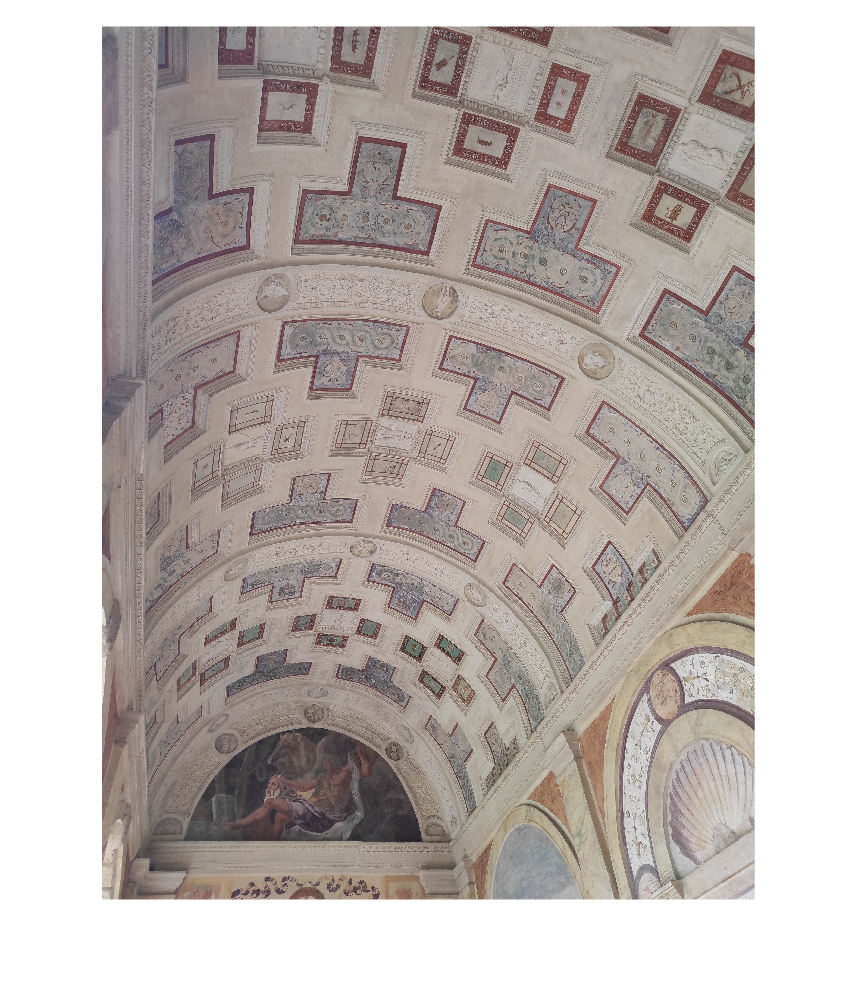

clear all;
im = imread('PalazzoTe.jpg');

%rotate the image
img=imrotate(im, -90);

%show the image
imshow(img);

## **Import necessary geometric elements**

C1=load('elements\CONICS\C1.mat').C1

C1 =     0.0000   -0.0000   -0.0000
   -0.0000    0.0000   -0.0004
   -0.0000   -0.0004    1.0000


C2=load('elements\CONICS\C2.mat').C2

C2 =     0.0000   -0.0000   -0.0001
   -0.0000    0.0000   -0.0002
   -0.0001   -0.0002    1.0000


## **CONIC INTERSECTION**

[s1,s2,s3,s4]=intersection_two_conics(C1,C2)

s1 = 1.0e+03 *

   2.2498 - 4.0141i
   0.0644 - 1.1343i
   0.0010 + 0.0000i


s2 = 1.0e+03 *

   2.2498 + 4.0141i
   0.0644 + 1.1343i
   0.0010 + 0.0000i


s3 = 1.0e+03 *

    0.4347
    3.3731
    0.0010


s4 = 1.0e+03 *

    2.2261
    4.0416
    0.0010


save('elements\CIRCULAR POINTS\I.mat' , 's1')
save('elements\CIRCULAR POINTS\J.mat' , 's2')


## **HORIZON**

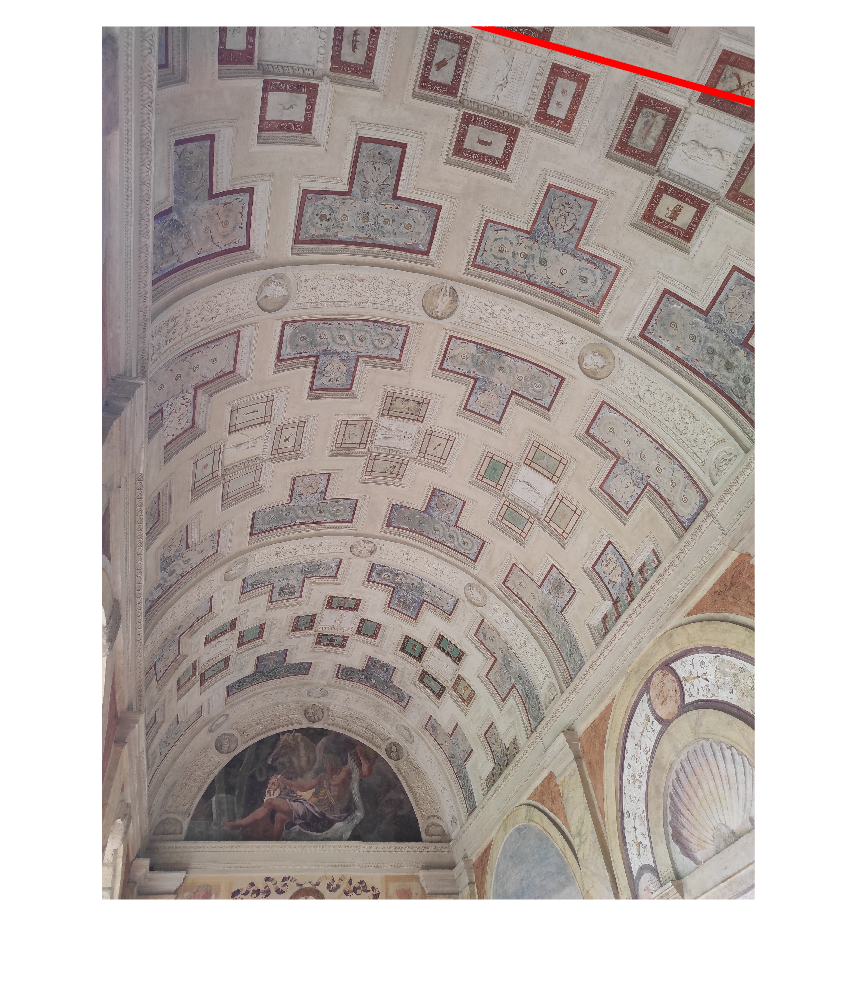

horizon =    -0.0005
    0.0018
    1.0000


horizon=line_through_two_pts(s1,s2,img,true)

save('elements\LINES\horizon.mat' , 'horizon')


